clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);
load("testGT.mat")

% Calculating PCA
[image,components] = PCA(hcube,5);

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% Define your class labels here. This should be a vector of the same length as the number of pixels.
labels = classMap;
labels = reshape(labels, [], size(labels, 3));
% Obtaining image's sizes
[rows, cols, ~] = size(image);

% Divide the image into four equal parts
part_rows = floor(rows / 2);
part_cols = floor(cols / 2);

% Create a mask for the testing part (e.g., top left quarter)
test_mask = false(rows, cols);
test_mask(1:part_rows, 1:part_cols) = true;

% Flatten the mask to have the same shape as 'pixels' and 'labels'
test_mask = reshape(test_mask, [], 1);

% Split data into training and testing sets
pixelsTrain = pixels(~test_mask,:);
labelsTrain = labels(~test_mask,:);
pixelsTest = pixels(test_mask,:);
labelsTest = labels(test_mask,:);

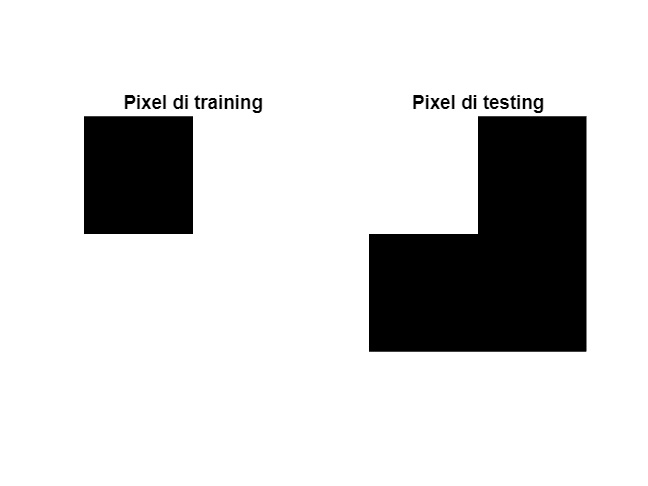

% Reshape the labels to match the original image shape
labels_img = reshape(labels, [rows, cols]);

% Create a mask for the training part
train_mask = ~test_mask;

% Reshape the masks to match the original image shape
test_mask_img = reshape(test_mask, [rows, cols]);
train_mask_img = reshape(train_mask, [rows, cols]);

% Create a new figure
figure;

% Display the training pixels in a subplot
subplot(1, 2, 1);
imshow(train_mask_img);
title('Pixel di training');

% Display the testing pixels in another subplot
subplot(1, 2, 2);
imshow(test_mask_img);
title('Pixel di testing');


% Show the figure
drawnow;

pixelsTrainGPU = gpuArray(pixelsTrain);

Error using gpuArray
Unable to find a supported GPU device.

Related documentation

labelsTrainGPU = gpuArray(labelsTrain);

% Random Forest training
numTrees = 500; % Increase the number of trees
RFmodel = TreeBagger(numTrees, pixelsTrainGPU, labelsTrainGPU, 'Method', 'classification', 'OOBPrediction', 'on');
%RFmodel = TreeBagger(numTrees, pixelsTrain, labelsTrain, 'Method', 'classification', 'OOBPrediction', 'on');

% Predict classes on test data
%[idx_rf,scores] = predict(RFmodel, pixelsTest);
pixelsTestGPU = gpuArray(pixelsTest); % Trasferisci i dati di test sulla GPU
predictedLabels = predict(RFmodel, pixelsTestGPU);

% Convert cell array of predictions to matrix
idx_rf = cellfun(@str2double, idx_rf);

% Calculate accuracy on test data
accuracy = sum(labelsTest == idx_rf) / length(labelsTest);

% Print accuracy
fprintf('Accuracy of the model is %f\n', accuracy);

% Prepare the result image (initialize with zeros)
image_result = zeros(rows, cols);

% Fill the testing part of the result image with the predicted labels
image_result(test_mask) = idx_rf;

% Plot results
figure;
imshow(image_result, []);
colormap(jet(max(idx_rf))); % Use the maximum cluster label to define the colormap range
colorbar;
title('Random Forest classification results');
